%% PROJECT 1: F1 OPTIMIZATION (BASIC KINEMATIC + ELASTIC RACELINE)
% Modèle : Point Mass, Friction statique constante.
% Optimisation : Heuristique "Elastic Band".
% Voiture : RB16 (2020) simplifiée.

clear; close all; clc;

%% 1. PARAMÈTRES (RB16 SIMPLIFIÉE)
% ---------------------------------------------------------
filename = fullfile(pwd, 'Nuerburgring_track.csv'); % Ton fichier
ds = 2.0;               % Pas de discrétisation (m)

% Véhicule
m = 746;                % Masse (kg)
P_max = 735500;         % Puissance (Watts) ~1000ch
F_max = 18000;          % Traction Max (N)
F_brake = 42000;        % Freinage Max (N)
v_max_abs = 330 / 3.6;  % Vitesse max absolue (m/s)

% Friction "Équivalente"
% Comme on enlève l'aéro, on augmente mu pour simuler le grip moyen d'une F1
mu = 2.7;               
g = 9.81;

%% 2. CHARGEMENT PISTE (CSV VARIABLE WIDTH)
% ---------------------------------------------------------
try
    T_data = readtable(filename, "ReadVariableNames", true); 
    
    % Extraction robuste des colonnes
    if ismember('x_X_m', T_data.Properties.VariableNames)
        x_c = T_data.x_X_m; y_c = T_data.y_m;
        w_r = T_data.w_tr_right_m; w_l = T_data.w_tr_left_m;
    elseif ismember('x_m', T_data.Properties.VariableNames)
        x_c = T_data.x_m; y_c = T_data.y_m;
        w_r = T_data.w_tr_right_m; w_l = T_data.w_tr_left_m;
    else
        x_c = table2array(T_data(:,1)); y_c = table2array(T_data(:,2));
        w_r = table2array(T_data(:,3)); w_l = table2array(T_data(:,4));
    end
    
    width_raw = w_r + w_l;

catch ME
    error('Erreur CSV: %s', ME.message);
end


% Nettoyage et Splines
d2 = diff(x_c).^2 + diff(y_c).^2; 
idx_ok = [true; d2 > 1e-5];
x_c = x_c(idx_ok); y_c = y_c(idx_ok); width_raw = width_raw(idx_ok);

% Fermeture boucle
if norm([x_c(1)-x_c(end), y_c(1)-y_c(end)]) > 2
    x_c(end+1) = x_c(1); y_c(end+1) = y_c(1); width_raw(end+1) = width_raw(1);
end

% Interpolation
dist_s = sqrt(diff(x_c).^2 + diff(y_c).^2); t_raw = [0; cumsum(dist_s)];
pp_x = spline(t_raw, x_c); pp_y = spline(t_raw, y_c); pp_w = spline(t_raw, width_raw);

S_final = 0 : ds : t_raw(end);
x_center = ppval(pp_x, S_final);
y_center = ppval(pp_y, S_final);
track_width = ppval(pp_w, S_final); 
track_width(track_width < 6) = 6; % Sécurité largeur min

fprintf('Piste chargée. Longueur: %.0fm\n', S_final(end));

Piste chargée. Longueur: 5144m



%% 3. OPTIMISATION TRAJECTOIRE (MÉTHODE ÉLASTIQUE)
% ---------------------------------------------------------
fprintf('Optimisation Trajectoire (Elastic Band)...\n');

Optimisation Trajectoire (Elastic Band)...



x_opt = x_center; 
y_opt = y_center;
N = length(x_opt);
iterations = 100; 
alpha = 0.5;

for k = 1:iterations
    for i = 2:N-1
        % 1. Lissage (Tendre vers la corde)
        xm = (x_opt(i-1) + x_opt(i+1)) / 2;
        ym = (y_opt(i-1) + y_opt(i+1)) / 2;
        xn = (1-alpha)*x_opt(i) + alpha*xm;
        yn = (1-alpha)*y_opt(i) + alpha*ym;
        
        % 2. Contrainte (Rester sur la piste)
        % On calcule la distance par rapport au CENTRE FIXE
        dist = sqrt((xn - x_center(i))^2 + (yn - y_center(i))^2);
        limit = track_width(i) / 2 - 1.0; % Marge de sécurité 1m
        
        if dist < limit
            x_opt(i) = xn; y_opt(i) = yn;
        else
            % Projection sur le bord
            ratio = limit / dist;
            x_opt(i) = x_center(i) + (xn - x_center(i)) * ratio;
            y_opt(i) = y_center(i) + (yn - y_center(i)) * ratio;
        end
    end
    % Boucle fermée
    x_opt(1)=x_opt(N); y_opt(1)=y_opt(N);
end

%% 4. CALCUL PHYSIQUE (CENTERLINE vs OPTIMISÉE)
% ---------------------------------------------------------
[v_center, T_center] = Compute_Speed_Profile(x_center, y_center, ds, m, P_max, F_max, F_brake, mu, g, v_max_abs);
[v_opt, T_opt]       = Compute_Speed_Profile(x_opt, y_opt, ds, m, P_max, F_max, F_brake, mu, g, v_max_abs);

fprintf('\n=== RÉSULTATS ===\n');


=== RÉSULTATS ===


fprintf('Temps Centerline : %.2f s\n', T_center);

Temps Centerline : 91.11 s


fprintf('Temps Optimisé   : %.2f s\n', T_opt);

Temps Optimisé   : 88.42 s


fprintf('GAIN             : -%.2f s\n', T_center - T_opt);

GAIN             : -2.70 s


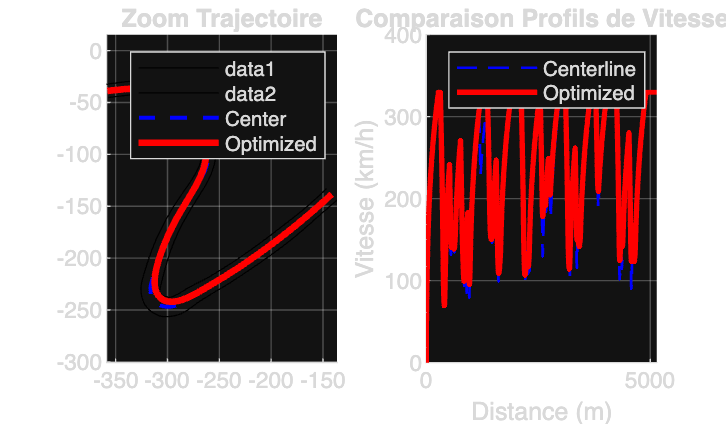


%% 5. VISUALISATION
% ---------------------------------------------------------
figure('Name', 'Comparaison Basic', 'Color', 'w', 'Position', [50 50 1200 700]);

% Plot 1: Zoom Géométrique
subplot(1,2,1); hold on; grid on; axis equal;
idx = 100:350; % Zoom sur le premier secteur
% Bords approximatifs pour visu
norm_x = -gradient(y_center); norm_y = gradient(x_center); 
len = sqrt(norm_x.^2 + norm_y.^2); norm_x=norm_x./len; norm_y=norm_y./len;
plot(x_center(idx)+norm_x(idx).*track_width(idx)/2, y_center(idx)+norm_y(idx).*track_width(idx)/2, 'k-');
plot(x_center(idx)-norm_x(idx).*track_width(idx)/2, y_center(idx)-norm_y(idx).*track_width(idx)/2, 'k-');

plot(x_center(idx), y_center(idx), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Center');
plot(x_opt(idx), y_opt(idx), 'r-', 'LineWidth', 2.5, 'DisplayName', 'Optimized');
legend; title('Zoom Trajectoire');

% Plot 2: Vitesse
subplot(1,2,2); hold on; grid on;
plot(S_final, v_center*3.6, 'b--', 'LineWidth', 1);
plot(S_final, v_opt*3.6, 'r-', 'LineWidth', 2);
legend('Centerline', 'Optimized');
xlabel('Distance (m)'); ylabel('Vitesse (km/h)');
title('Comparaison Profils de Vitesse'); xlim([0 S_final(end)]);



%% FONCTION PHYSIQUE (BASIC)
function [v_final, T_total] = Compute_Speed_Profile(x, y, ds, m, P_max, F_max, F_brake, mu, g, v_top)
    
    n = length(x);
    dx = gradient(x, ds); dy = gradient(y, ds);
    ddx = gradient(dx, ds); ddy = gradient(dy, ds);
    k = abs((dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5)); k(isnan(k)) = 0;

    % Limite Statique (Basic: v = sqrt(mu*g/k))
    v_limit = sqrt((mu * g) ./ (k + 1e-6));
    v_limit = min(v_limit, v_top);

    % Forward
    v_fwd = zeros(1, n);
    for i = 1:n-1
        v = max(v_fwd(i), 1);
        F_eng = min(F_max, P_max / v);
        a = F_eng / m; % F=ma simple
        v_next = sqrt(v_fwd(i)^2 + 2*a*ds);
        v_fwd(i+1) = min(v_next, v_limit(i+1));
    end

    % Backward
    v_bwd = zeros(1, n); v_bwd(end) = v_fwd(end);
    for i = n:-1:2
        a = F_brake / m;
        v_prev = sqrt(v_bwd(i)^2 + 2*a*ds);
        v_bwd(i-1) = min(v_prev, v_limit(i-1));
    end

    v_final = min(v_fwd, v_bwd);
    T_total = sum(ds ./ max(v_final, 1));
end